% DEFINE STATE-SPACE MODEL

A = [-0.313 56.7 0; -0.0139 -0.426 0; 0 56.7 0];
B = [0.232; 0.0203; 0];
C = [0 0 1];
D = [0];

stsp = ss(A,B,C,D)


stsp =
 
  A = 
            x1       x2       x3
   x1   -0.313     56.7        0
   x2  -0.0139   -0.426        0
   x3        0     56.7        0
 
  B = 
           u1
   x1   0.232
   x2  0.0203
   x3       0
 
  C = 
       x1  x2  x3
   y1   0   0   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


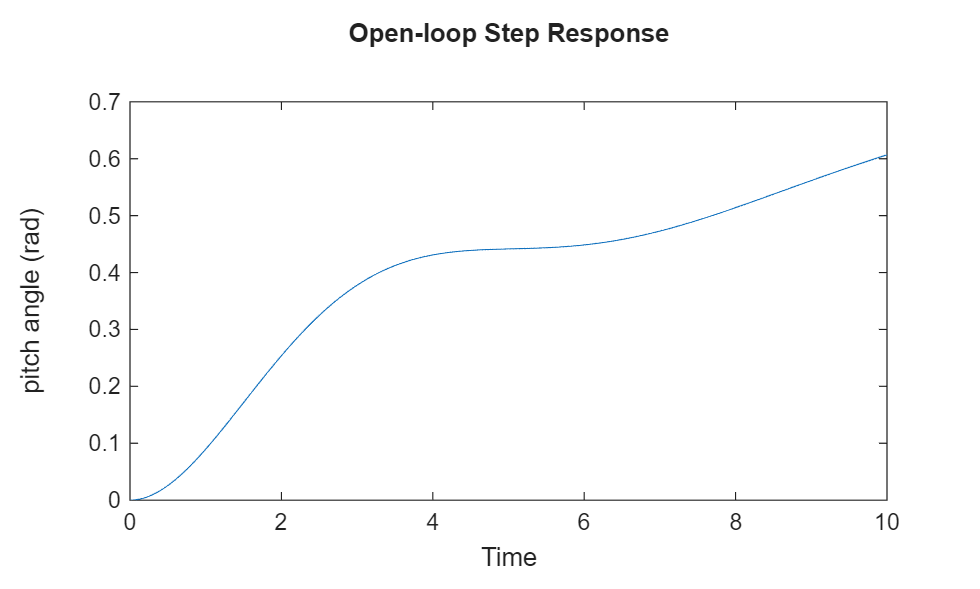

% OPEN LOOP TRANSFER FUNCTION AND RESPONSE

tf_sys = tf(stsp);

t = [0:0.01:10];
step(0.2*tf_sys,t);
axis([0 10 0 0.8]);
ylabel('pitch angle (rad)');
title('Open-loop Step Response');

%% CONTROLLABILITY

co = ctrb(A,B);

Con = rank(co)

Con = 3

%% OPEN LOOP POLES
eig_A = eig(A);

disp('Open-loop Eigenvalues:');

Open-loop Eigenvalues:


disp(eig_A);

   0.0000 + 0.0000i
  -0.3695 + 0.8860i
  -0.3695 - 0.8860i



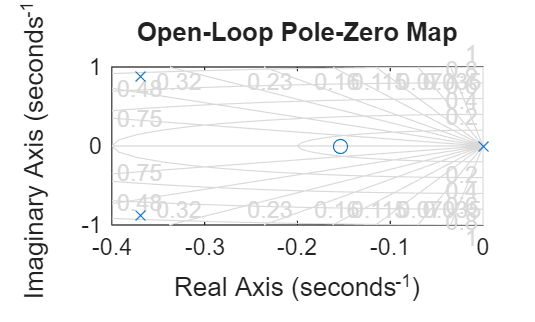


figure;
pzmap(stsp);
title('Open-Loop Pole-Zero Map');
grid on;

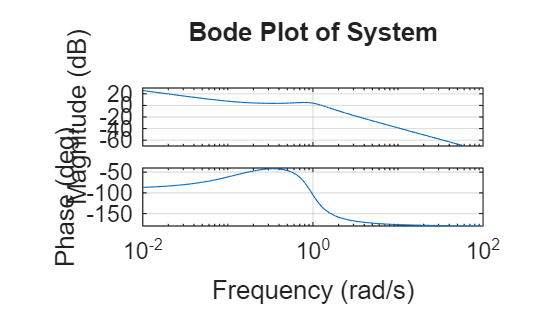

% OPEN LOOP STABILITY


bode(tf_sys);
grid on;
title('Bode Plot of System');

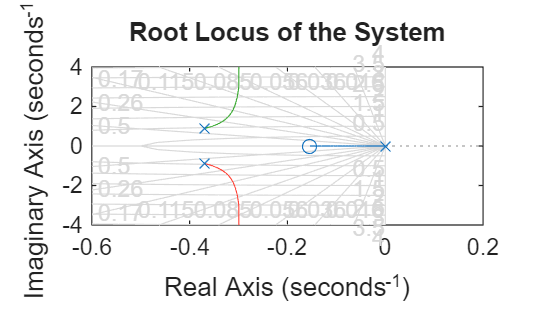



rlocus(tf_sys);
grid on;
title('Root Locus of the System');

xlabel('Real Axis');
ylabel('Imaginary Axis');



% CLOSED LOOP TRANSFER FUNCTION AND RESPONSE

p = 50;
Q = p*C'*C;
R = 1;
K = lqr(A,B,Q,R)

K =    -0.6435  169.6950    7.0711


sys_cl = ss(A-B*K, B, C, D);
step(0.2*sys_cl)
tf_cl = tf(sys_cl)


tf_cl =
 
          1.151 s + 0.1774
  ---------------------------------
  s^3 + 4.035 s^2 + 8.787 s + 1.255
 
Continuous-time transfer function.


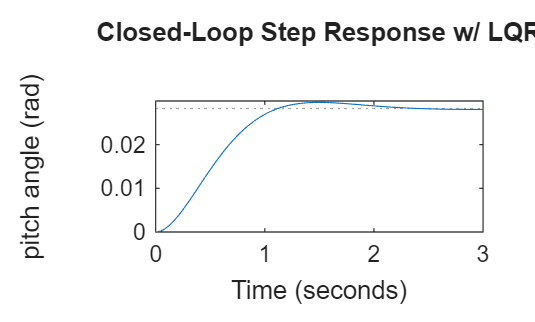

ylabel('pitch angle (rad)');
title('Closed-Loop Step Response w/ LQR');

info = stepinfo(sys_cl);
disp(info)

         RiseTime: 0.7283
    TransientTime: 2.0181
     SettlingTime: 2.0181
      SettlingMin: 0.1291
      SettlingMax: 0.1484
        Overshoot: 4.9126
       Undershoot: 0
             Peak: 0.1484
         PeakTime: 1.4950

